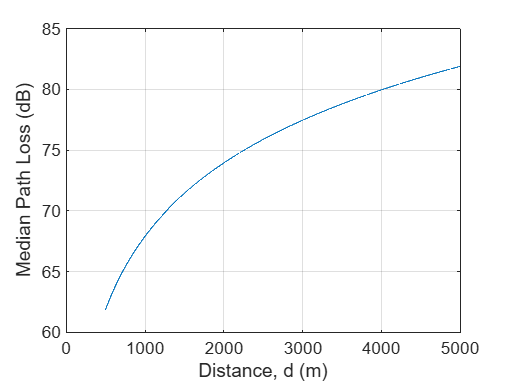

clc;
 clear all;
 close all;
 hte = input("Enter the transmitting antenna height in m : ");
 hre = input("Enter the receiving antenna height in m : ");
 d =(500:5000);
 f=900*10^6;
 amu=43;
 Garea=19;
 lambda=3*10^8/f;
 Lf=20*log10(lambda/4*pi.*d);
 Ghre=20*log10(hre/3);
 Ghte=20*log10(hte/200);
 L50=Lf+amu-Ghre-Ghte-Garea;
 plot(d,L50)
 xlabel("Distance, d (m)")
 ylabel("Median Path Loss (dB)")
 grid on;